# Investigate Features of Misclassified Samples

Instructions are in the task pane to the left. Complete and submit each task one at a time.

% Do not edit. This code loads the data and a trained kNN model.
load letterdata.mat
load predmodel.mat
traindata

traindata = 2907×26 table
    AspectRatio      MADX       MADY        AvgU       MADU         AvgV        MADV      CorrXY       CorrXP      CorrXU      CorrXV      CorrYP       CorrYU      CorrYV       CorrPU       CorrPV       CorrUV      NumXMin    NumXMax    NumYMin    NumYMax    NumUMin    NumUMax    NumVMin    NumVMax    Character
    ___________    ________    _______    ________    _______    __________    ______    ___

testdata

testdata = 968×26 table
    AspectRatio     MADX       MADY        AvgU        MADU        AvgV       MADV      CorrXY      CorrXP       CorrXU       CorrXV       CorrYP       CorrYU        CorrYV       CorrPU      CorrPV       CorrUV     NumXMin    NumXMax    NumYMin    NumYMax    NumUMin    NumUMax    NumVMin    NumVMax    Character
    ___________    _______    _______    _________    _______    ________    ______    _______

predLetter

predLetter = 968×1 categorical array
     E 
     F 
     G 
     J 
     M 
     P 
     T 
     Z 
     D 
     M 
     G 
     R 
     S 
     T 
     K 
     B 
     C 
     D 
     T 
     I 
     K 
     O 
     R 
     S 
     V 
     V 
     Z 
     E 
     G 
     J 


## Task 1

Having identified examples of interest, you will typically want to examine the corresponding features.

**TASK**

Use logical indexing to extract the **training data** for just the letters N and U. Store the result in a table called `UorN`.

Similarly, extract the **test data** where the letter U was misclassified (i.e., the false negatives for U). Store the result in a table called `fnU`

**Hint**

Use the `==` and `|` operators to make a logical array that determines where `traindata.Character` has the value `"N"` or `"U"`. Use this as an index into the rows of `traindata`. Similarly, make a logical array that determines where `testdata.Character` has the value `"U"` but `predLetter` does not have the value `"U"`.

idx = (traindata.Character == "N") | (traindata.Character == "U");
UorN = traindata(idx,:)

UorN = 219×26 table
    AspectRatio     MADX       MADY       AvgU       MADU        AvgV       MADV      CorrXY      CorrXP      CorrXU        CorrXV       CorrYP       CorrYU      CorrYV      CorrPU       CorrPV       CorrUV      NumXMin    NumXMax    NumYMin    NumYMax    NumUMin    NumUMax    NumVMin    NumVMax    Character
    ___________    _______    _______    _______    _______    ________    ______    ________


idx = (testdata.Character == "U") & (predLetter ~= "U");
fnU = testdata(idx,:)

fnU = 17×26 table
    AspectRatio     MADX       MADY       AvgU       MADU        AvgV       MADV      CorrXY      CorrXP       CorrXU      CorrXV       CorrYP       CorrYU      CorrYV      CorrPU        CorrPV       CorrUV      NumXMin    NumXMax    NumYMin    NumYMax    NumUMin    NumUMax    NumVMin    NumVMax    Character
    ___________    _______    _______    _______    _______    ________    ______    ________ 

%%Ta

## Task 2

Categorical variables maintain the full list of possible classes, even when only a subset are present in the data. When examining a subset, it can be useful to redefine the set of possible classes to only those that are in the data. The `removecats` function removes unused categories.

`cmin` `=` `removecats``(``cfull``)`

**TASK**

Use the `removecats` function to remove unused categories from `UorN.Character`. Assign the result back to `UorN.Character`.

**Hint**

Pass `UorN.Character` as an input to the `removecats` function. Assign the result back to `UorN.Character`.

UorN.Character = removecats(UorN.Character);

## Task 3

You can use curly braces (`{` `}`) to extract data from a table into an array of a single type.

`datamatrix` `=` `datatable``{``1``:``10``,``4``:``6``}`

This extracts the first 10 elements of variables 4, 5, and 6. If these variables are numeric, `datamatrix` will be a 10-by-3 double array.

**TASK**

Extract the numeric feature data from `UorN` and `fnU` into matrices called `UorNfeat` and `fnUfeat`, respectively.

Note that the last variable in both tables is the response. All other variables are the features.

**Hint**

Use the syntax `UorN``{``rows``,``vars``}` to extract all rows and all but the last variable (i.e., variables 1 through `end``-1`).

UorNfeat = UorN{:,1:end-1};
fnUfeat = fnU{:,1:end-1};

## Task 4

A *parallel coordinates* plot shows the value of the features (or “coordinates”) for each observation as a line.

`parallelcoords``(``data``)`

To compare the feature values of different classes, use the `"Group"` option.

`parallelcoords``(``data``,``"Group"``,``classes``)`

**TASK**

Use the `parallelcoords` function to plot the features in the training data (`UorNfeat`), grouped by letter (`UorN.Character`).

**Hint**

Pass `UorNfeat` as an input to the `parallelcoords` function. Set the `"Group"` option to `UorN.Character`.

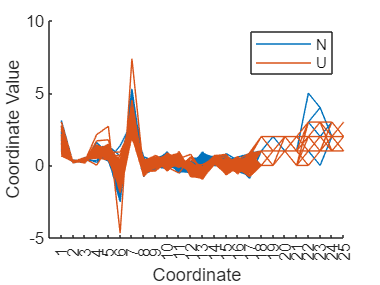

parallelcoords(UorNfeat,"Group",UorN.Character)

## Task 5

Because a parallel coordinates plot is just a line plot, you can add individual observations using the regular `plot` function.

**TASK**

Use the `plot` function to add the values of the features for the fourth misclassified U to the plot as a black line. (The features for the misclassified letters are stored in the matrix `fnUfeat`).

**Hint**

Pass the fourth row of `fnUfeat` as an input to the `plot` function. Use the line style specification `"k"`.

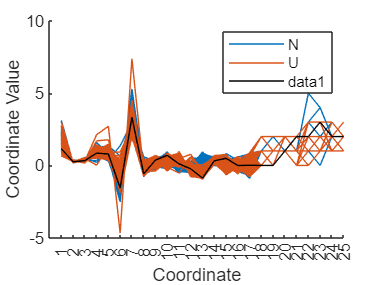

hold on
plot(fnUfeat(4,:),"k")
hold off

## Further Practice

Use the zoom tool to explore the plot. Note that N and U have similar values for many features. Are there any features that help distinguish these letters from each other? A kNN model uses the distance between observations, where the distance is calculated over all the features. Does this explain why N and U are hard to distinguish, even if there are some features that separate them?

When plotting multiple observations by groups, it can be helpful to view the median and a range for each group, rather than every individual observation. You can use the `"Quantile"` option to do this.

`parallelcoords``(``...,``"Quantile"``,``0.2``)`

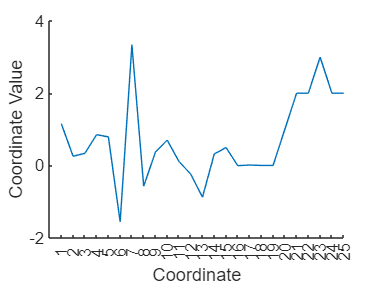

parallelcoords(fnUfeat(4,:),"Quantile",0.2)